## Section: Plotting

**New**: **Plotting **is one of the main parts of Matlab. A basic plot can be done with the **plot(x,y) **function. Where x is the x-axis and y is the y-axis.

Link: [2-D line plot - MATLAB plot - MathWorks Deutschland](https://de.mathworks.com/help/matlab/ref/plot.html#btzitot_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8)

Example:

x = 1:10;
y = rand(10,1);
plot(x,y,'*') % different dote styls
xlabel('x-axis')
ylabel('random numbers')
title('first plot')

**Exercise**: 

- Clear you workspace, command window and close all plots

- Plot a linear function with y = m*x + c, where m = 2 and c = 1

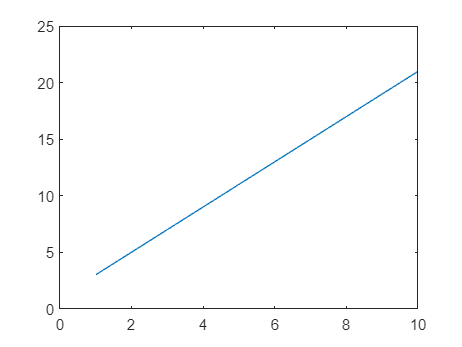

clear all
close all
clc
x = 1:10;
y = 2.* x + 1;
plot(x,y)

% your code


**New**: Importing data (2 ways)

- Using Import Data App

- Using one of many import functions, we are using the **readtable**(data) function

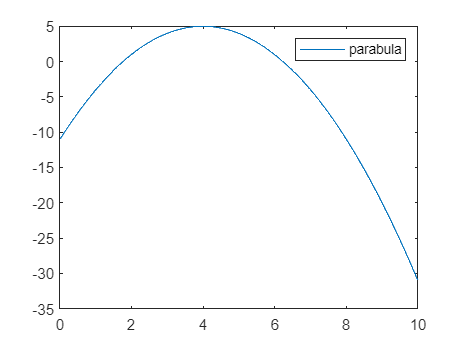

data = readtable('exampleData.csv'); % imports data as table
data = table2array(data); % data is turned numeric
xData = data(:,1);
yData = data(:,2);
plot(xData,yData)
legend('parabula')

Also **new**: Accessing of data of multidimensional arrays 

**New**: **max**(data), **min**(data) those functions will find the Minimum or Maximum of a data set

Exercise: Find the Minimum and the Maximum of the y-data set

- Advanced: Also find the index of the Minimum/Maximum (hint: look for [`[M,I] = min(``___``)`](https://de.mathworks.com/help/matlab/ref/min.html#d123e931907)` ) and `print it to the console/live script.

% your code


## Section: Functions and Fitting

**Little excurse exercise: **Create an extra Matlab file and import the data from the exercise before and run it.

- (Together) Lets have a look at the PLOTS application of Matlab

- (Together) Lets also have a look at the Figure Palette

- Installation of the curve fitting toolbox

- Using the curve fitting toolbox

**Exercise:**

create a new .m file for the next points:

- load weirdPoly.csv to workspace and open it with curve fitting toolbox; try to fit it with polynomial fit

- load sin.csv => try to fit it with sine => you will notice that it doesn´t work as you planned => There for: create your own custom function a*sin(b*x) + c

- load sinc.csv => google for sinc-function and try to fit it (you don´t need to understand the function)

**New**: Creation of mathematical functions; This is important for fitting data. The goal is to rebuild this function: f(x) = a * (x-b)^2 + c

data = readtable('exampleData.csv'); % imports data as table
data = table2array(data); % data is turned numeric
xData = data(:,1);
yData = data(:,2);

fun = @(x, xdata) x(1).*(xdata - x(2)).^2 + x(3) %symbolic function
x = [1 2 3];
% plot(xData, fun(x,xData))


**New**: First fit method `x = lsqcurvefit(fun,x0,xdata,ydata) `this method solves nonlinear equation with a least square algorithm

Link: [Solve nonlinear curve-fitting (data-fitting) problems in least-squares sense - MATLAB lsqcurvefit - MathWorks Deutschland](https://de.mathworks.com/help/optim/ug/lsqcurvefit.html)

x0 = [-1 1 1]; %initial values
x = lsqcurvefit(fun,x0,xData,yData)

plot(data(:,1),data(:,2),'.')
hold on
plot(xData, fun(x,data(:,1)))

fun = function_handle with value:
    @(x,xdata)x(1).*(xdata-x(2)).^2+x(3)


**New**: Smoothing of data; Sometimes our data is really noisy. TO reduce the noise we can use smooth()

data = readtable('sinNoisy.csv');
data = table2array(data);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =    -1.0000    4.0000    5.0000


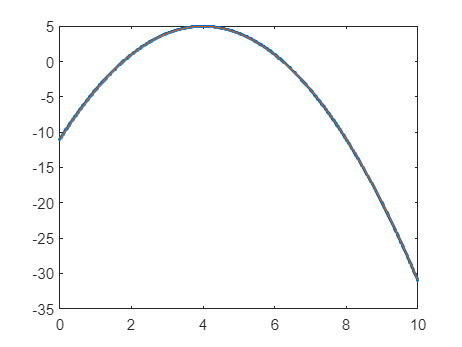


figure() % generates a seperate plot
plot(data(:,1),data(:,2))
hold on

Now try to use the smooth()-function (google the function), to smooth the y-data. Try different smoothing windows/spans and plot the smoothed data to compare it with the original.

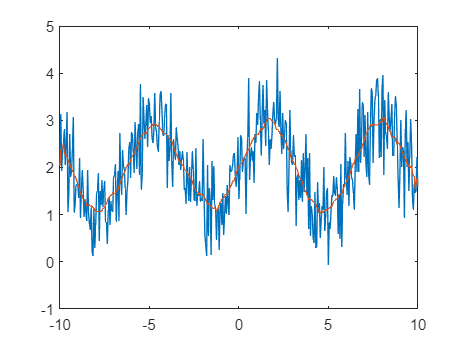

smoothed = smooth(data(:,2), 30);
plot(data(:,1),smoothed)